# Controle Servo Motores

Neste exemplo, mostramos como usar o MATLAB® Support Package for Arduino® Hardware para controlar um servo motor.

## Configuração do Componentes (Hardware)

Conectar um SG90 servo motor no Arduino,

- Conecte o cabo de força (normalmente vermelho) no pino 5V.

- Conecte o cabo de terra (normalmente preto, neste servo marrom) ao pino de terra (GND).

- Conecte o cabo de sinal (normlamente laranja) ao pino digital 4.

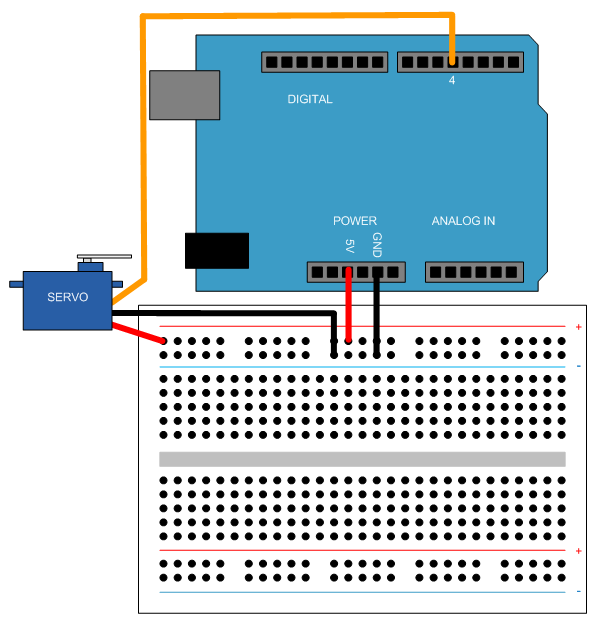

## Criar um objeto servo e calibrar o motor motor

Criar um objeto arduino e incluir a biblioteca Servo. 

a = arduino();

Ou, você pode especificar na criação do objeto arduino, no par de chamada Biblioteca e Valor.

clear a;
a = arduino('COM3', 'Uno', 'Libraries', 'Servo');

Criando um objeto Servo.

s = servo(a, 'D4')

s =   Servo with properties:

                 Pin: 'D4'
    MinPulseDuration: 5.44e-04 (seconds)
    MaxPulseDuration: 2.40e-03 (seconds)


Verifique a especificação de seu servo motor para os valores do pulso para calibrar o motor no limite esperado. Neste Exemplo usamos 600*10^-6 e 2600*10^-6 para o motor mover de 0 a 180 graus.

# 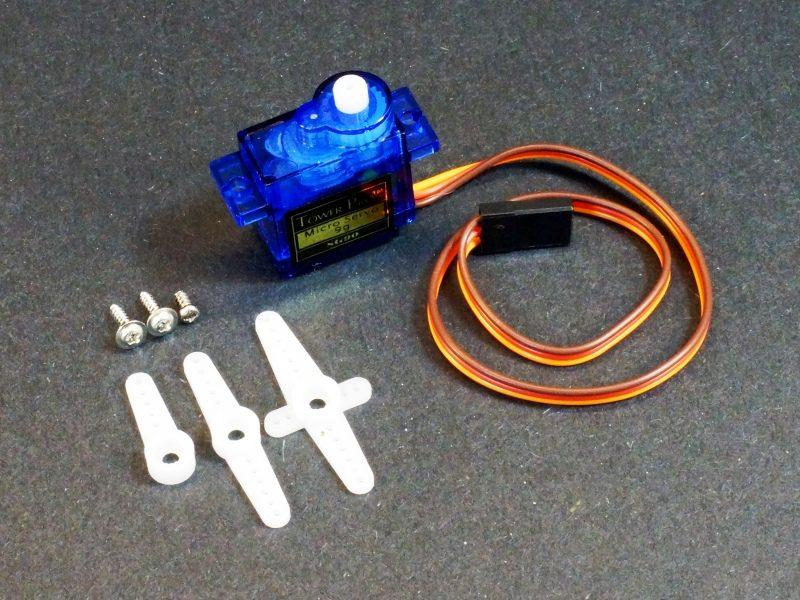

clear s;
s = servo(a, 'D4', 'MinPulseDuration', 600*10^-6, 'MaxPulseDuration', 2600*10^-6)

s =   Servo with properties:

                 Pin: 'D4'
    MinPulseDuration: 6.00e-04 (seconds)
    MaxPulseDuration: 2.60e-03 (seconds)


## Ler e Escrever a posição de um Servo motor

Mudano a posição do servo motor de 0(minimo) a 1(maximo) com 0.25, e.g 45 graus. Visualziar a posição atual a cada mudança de posição no tempo.

for angulo = 0:0.25:1
    writePosition(s, angulo);
    pos_atual = readPosition(s);
    pos_atual = pos_atual*180;
    fprintf('Posição do Motor é %d graus\n', pos_atual);
    pause(2);
end

Posição do Motor é 0 graus
Posição do Motor é 45 graus
Posição do Motor é 90 graus
Posição do Motor é 135 graus
Posição do Motor é 180 graus


## Limpeza

Quando a conexão não é mais necessária, limpe o objeto associado.

clear s a

*Copyright 2014-2016 The MathWorks, Inc.*